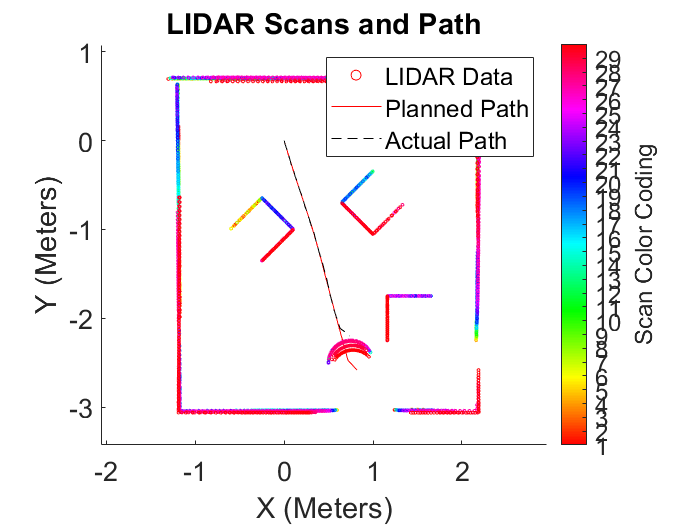

clear 
load DriveCodeV4_Storage_2.mat
number_of_scans = size(lidar_storage,1)/360;

clf; hold on
scatter3(lidar_storage(:,3),lidar_storage(:,4),lidar_storage(:,5),3,lidar_storage(:,5),"DisplayName","LIDAR Data"); colormap("hsv");
% configure colorbar
colorbar;
c = colorbar;
c.Label.String = 'Scan Color Coding';
c.Ticks = linspace(2,number_of_scans,number_of_scans);
c.TickLabels = num2cell(1:number_of_scans);
%configure rest of graph
title("LIDAR Scans and Path")
xlabel("X (Meters)");
ylabel("Y (Meters)");
legend()
plot(x_global,y_global,"r-","MarkerSize",5,"DisplayName","Planned Path")
plot(real_position_storage(:,1),real_position_storage(:,2),"k--","DisplayName","Actual Path")
axis equal
set(gca, "FontSize",16)
set(gca, 'color', [1 1 1])
set(gcf, 'color', [1 1 1])

start_time = lidar_storage(1,6)

start_time = single
276.2000

end_time = lidar_storage(end,6) %these are rough numbers

end_time = single
314.5890

total_time = end_time - start_time

total_time = single
38.3890